clear;

% define lattice area
N = 27;



## Define Variables

couplingConstant = 1; %eV
Jmat = couplingConstant.*[1 1 1 1 1 1];
Jz_coupling = [0.1 1 3 10 100];
T = 1;

T_c = 2.27;
k_b = 8.617333262*10^-5;%eV/K
%beta = couplingConstant/(k_b.*T);
beta = 0.1:0.1:3;



%T = [100000:-1000:1];

h = 0;

steps = 100;

%currentLattice = figure;


## Run simulation 

for count = 1:length(Jz_coupling)
    
    Jz = Jz_coupling(count);
    %beta = couplingConstant./(k_b.*T);
    
    
    % define lattice
    A = zeros(N);
    B = initializeLattice(N, 0, 0, 0);
    C = initializeLattice(N, 0, 0, 0);
    
    spins = cat(3, A, B, C, A);
    
    % show lattice
    %spinVis(spins)
    %tic
    
    for n = 1:length(beta)
        
        for t = 1:steps
            
            for k = 2:3
                for i = 2:(N-2)
                    for j = 2:(N-2)
                        
                        p = randi([2 N-2], 1, 2);
                        z = randi ([2 3], 1, 1);
                        x = p(1);
                        y = p(2);
                        
                        % boolean to see if to couple AFM or not
                        AFM_bool = ((mod(i,2)==0 && mod(j, 2)==0) ||...
                            (mod(i, 2) ~=0 && mod(j, 2) ~= 0));
                        
                        if z == 2 && AFM_bool
                            % looking up from FM layer to AFM layer
                            % want AFM coupling always
                            
                            J = Jmat;
                            %J(5) = -1*couplingConstant*J(5);
                            J(5) = 1* Jz * J(5);
                            temp = beta(n);
                            
                        elseif z == 2 && ~AFM_bool
                            J = Jmat;
                            %J(5) = -1*couplingConstant*J(5);
                            J(5) = Jz * J(5);
                            temp = beta(n);
                            
                        elseif z == 3 && AFM_bool
                            J = -1.*Jmat;
                            %J(6) = couplingConstant*J(6);
                            J(6) = -1*Jz*J(6);
                            temp = beta(n);
                            
                        elseif z==3 && ~ AFM_bool
                            J = -1.*Jmat;
                            %J(6) = couplingConstant*J(6);
                            J(6) = -1*Jz*J(6);
                            temp = beta(n);
                        end
                        
                        
                        delta_spin = -1*spins(x, y, z) - spins(x, y, z);
                        
                        J_Snn = J(1)*spins((x-1), y, z) +...
                            J(2)*spins((x+1), y, z) +...
                            J(3)*spins(x, (y-1), z) +...
                            J(4)*spins(x, (y+1), z) +...
                            J(5)*spins(x, y, (z+1)) +...
                            J(6)*spins(x, y, (z-1));
                        
                        %Snn = sumNN3D(spins, x, y, z);
                        
                        spins(x, y, z) = -1*spins(x, y, z);
                        
                        dE = delta_spin*(-1*J_Snn + h);
                        p = exp(-1*dE*temp);
                        r = rand;
                        
                        if dE < 0 || p >= r
                            continue
                        else
                            spins(x, y, z) = -1*spins(x, y, z);
                        end
                        
                        E_spin(i, j, k) = J_Snn + h*sum(spins, "all");
                        
                    end
                end
            end
            
            % Get Get energy of entire system for nth step
            E_i(n, t, count) = sum(E_spin, "all");
            
            
            nHS_temp(n, t) = n_HSfrac3D(spins);
            M_temp(n, t) = abs(sum(spins, 'all'))/(2*((N-2)^2));
            M_Lay1(n, t) = abs(sum(spins(:, :, 2), 'all')/((N-2))^2);
            M_Lay2(n, t) = abs(sum(spins(:, :, 3), 'all')/((N-2))^2);
            
        end
        
        E(n, count) = mean(E_i(n, :, count));
        
        nHS(n, count) = mean(nHS_temp(n, :));
        M(n, count) = mean(M_temp(n, :));
        M1(n, count) = mean(M_Lay1(n, :));
        M2(n, count) = mean(M_Lay2(n, :));
        
        
        %     if mod(n, 10) == 0
        %         cc = abs(crossCorrelation(spins)./6);
        %         figure;
        %         imagesc(cc(:,:,1))
        %
        %         figure;
        %         imagesc(cc(:,:,2))
        %
        %     end
        
    end
    %toc

    %spinVis(spins)

    % figure;
    % plot(1./(T_c.*beta), nHS, '*-')
    % title("Average High Spin Fraction vs Temperature")
    % xlabel("T / T_c", "Interpreter","tex")
    % ylabel("nHS")

    % figure;
    % plot(1./(T_c.*beta), M, '.')
    % title("Magnetism vs Temperature")
    % xlabel("T / T_c", "Interpreter","tex")
    % ylabel("Magnetism")
    % hold on
    % plot(1./(T_c.*beta), M1, '.')
    % plot(1./(T_c.*beta), M2, '.')
    % legend('Total Mag', 'Layer 1 Mag', 'Layer 2 Mag')
    

    % figure;
    % imagesc([1:steps], 1./(T_c.*beta), M_temp)
    % xlabel("Time Step")
    % ylabel("T / T_c", "Interpreter","tex")
    % title("Net Magnetism Per Time Step vs Temperature")
    % c = colorbar;
    % c.Label.String = 'Net Magnetism';

    cc = (crossCorrelation(spins)./4);
    
    %     figure;
    %     imagesc(cc(:,:,1))
    %     axis square
    %     c = colorbar;
    %     caxis([-1 1])
    %
    %     figure;
    %     imagesc(cc(:,:,2))
    %     axis square
    %     c = colorbar;
    %     caxis([-1 1])

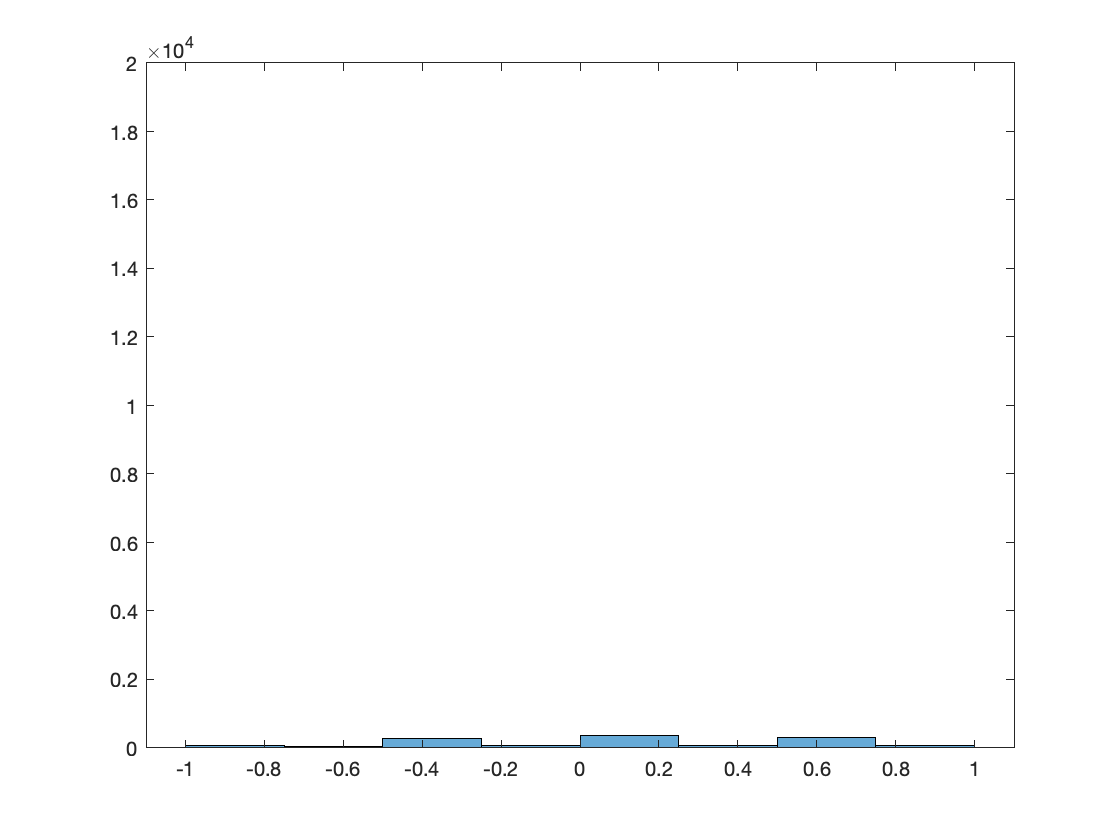

        V = cc(:);
        nbins = 8;
    %     figure
        histogram(V)
        X = histogram(V, nbins);

        ylim([0 20000])
        bins = X.BinEdges;
        val = X.Values;
        bin_width = X.BinWidth;
    %
        bin_centers = bins(1:nbins) + bin_width/2;
        couplingConstMat = Jz.*ones(1,nbins);

## Write data to text file

        fileID = fopen('data_AFM.txt','at');
        %fprintf(fileID,'%6s %12s\n','bin','count');
        fprintf(fileID,'%12.8f %12.8f %12.8f\n',[couplingConstMat; bin_centers; val]);
        fclose(fileID);
end



#### Look at Energy Change

E_i = squeeze(E_i);

figure;
plot(E_i)

Error using plot
Data cannot have more than 2 dimensions.


fourierTransform_E1 = fft(E_i(:, 1));
P2_E1 = abs(fourierTransform_E1);
P1_E1 = P2_E1(1:t/2+1);

Index exceeds the number of array elements (30).

P1_E1(2:end-1) = 2*P1_E1(2:end-1);
P1_E1 = P1_E1./max(P1_E1);


fourierTransform_E2 = fft(E_i(:, 2));
P2_E2 = abs(fourierTransform_E2);
P1_E2 = P2_E2(1:t/2+1);
P1_E2(2:end-1) = 2*P1_E2(2:end-1);
P1_E2 = P1_E2./max(P1_E2);

fourierTransform_E3 = fft(E_i(:, 3));
P2_E3 = abs(fourierTransform_E3);
P1_E3 = P2_E3(1:t/2+1);
P1_E3(2:end-1) = 2*P1_E3(2:end-1);
P1_E3 = P1_E3./max(P1_E3);

fourierTransform_E4 = fft(E_i(:, 4));
P2_E4 = abs(fourierTransform_E4);
P1_E4 = P2_E4(1:t/2+1);
P1_E4(2:end-1) = 2*P1_E4(2:end-1);
P1_E4 = P1_E4./max(P1_E4);

fourierTransform_E5 = fft(E_i(:, 5));
P2_E5 = abs(fourierTransform_E5);
P1_E5 = P2_E5(1:t/2+1);
P1_E5(2:end-1) = 2*P1_E5(2:end-1);
P1_E5 = P1_E5./max(P1_E5);

figure;
plot(P1_E1)
hold on
plot(P1_E2)
plot(P1_E3)
plot(P1_E4)
plot(P1_E5)
xlabel('Unitless')
ylabel('Arb Magnitude')
title('FFT of Energy-Time-Step Signal')
grid on
hold off


E1smoothed = smooth(P1_E1, 50);
E2smoothed = smooth(P1_E2, 50);
E3smoothed = smooth(P1_E3, 50);
E4smoothed = smooth(P1_E4, 50);
E5smoothed = smooth(P1_E5, 50);

figure;
plot(E1smoothed)
hold on
plot(E2smoothed)
plot(E3smoothed)
plot(E4smoothed)
plot(E5smoothed)
xlabel('Unitless')
ylabel('Arb Magnitude')
title('Smoothed FFT Energy Data')
grid on
hold off
legend({'0.1', '1', '3', '10', '100'})

